# Generate Data

clear;clc;
addpath("gendata_helper");
addpath("Tools");


We assume that the communication between agents are shown in graph.

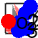


B=[0,1,1,0,0,0;
    1,0,1,1,0,0; 
    1,1,0,0,0,0;
    0,1,0,0,1,0;
    0,0,0,0,0,0
    0,1,0,0,0,0];

G=digraph(B);
str=["1","2","3","4","5","o"];
p=plot(G,'LineWidth',2,'EdgeColor','k','NodeColor','blue','ArrowSize',13,'layout','force','MarkerSize',8,'NodeFontSize',13,'NodeLabel',str); 
n6=successors(G,6);
highlight(p,6,'NodeColor','red')

highlight(p,6,n6,'EdgeColor','red','LineWidth',3.5)
highlight(p,2,4,'EdgeColor','red')
highlight(p,2,4,'EdgeColor','red')
highlight(p,2,3,'EdgeColor','red')
highlight(p,3,1,'EdgeColor','red')
highlight(p,4,5,'EdgeColor','red')

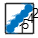



A=[1,0,0,0,1;
   0,1,1,1,0;
   0,1,1,0,0;
   0,1,0,1,1;
   1,0,0,1,1];
G=digraph(A);
plot(G)

figure()

## Generate Trajectory for Each Robot


T_WORKING=90; %
dti=0.01; %The sample interval of the IMU/estimator(s), i.e. IMU's frequency is 100Hz
scale=1;
dtc=0.03; %The sample interval of camera.
dt_object=0.05;
%
sigma_bg=0.01; 
sigma_ba=0.01; 
sigma_a=0.01; %%0.01
sigma_g=0.01;

b_g_real=[0.02,0.01,0.02];%bias 
b_a_real=[0.03,0.05,0.03];
g_real=[0;0;-9.81];

% Parameters related with camera
sigma_cam=0.5;  % pixels
fx=460;
fy=460;
cx=255;
cy=255;
image_w=640;
image_h=640;
p_camera_in_IMU_real = [0.0, 0.0, 0.0]/scale;
R_camera_in_IMU_real = angle2dcm(0,0 , 0);

%2. Effective measurement range (about landmark)
Eff_Range=3;

%3. Trajectory setting
% Assign initial positions for robots and center 

Position0=[1,0.8,0;
    10,-1.4,0;
    20,-2,1.5;
    8,-2, 2.5;
    1,-5,1];

%4. Generate object landmarks and assign bounding box
% Generate many landmarks
NL1=10;
NL2=10;
NL3=10;
NL4=10;
NL5=10;


%24,25


% 设置导入选项并导入数据
opts = delimitedTextImportOptions("NumVariables", 6, "Encoding", "UTF-8");

% 指定范围和分隔符
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% 指定列名称和类型
opts.VariableNames = ["x20_55", "x_1_95", "x0", "x1", "x2", "x_3_14"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% 指定文件级属性
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 导入数据
objectlist = readtable("D:\Desktop\Amao工作站\Simulations\1-5. Min SLAM\Min-SLAM3\object.csv", opts);

% 转换为输出类型
objectlist = table2array(objectlist);

% 清除临时变量
clear opts

% 显示结果
objectlist

objectlist =    -0.3800   -2.8700         0         0         0    1.4800
   -0.1300   -1.1000         0         0         0   -1.0500
    0.5000   -2.8400         0         0         0    1.7500
    0.6200   -1.1000         0         0         0   -1.8300
    1.1900   -2.1900    2.1900         0         0   -3.1400
    1.3000   -2.9000         0         0         0    1.3100
    2.0500   -2.9100         0         0         0    2.0900
    3.0500   -2.0200    2.4400   -1.5700    0.0600   -1.5700
    4.0800    2.4900    1.0700         0         0   -1.5700
    4.1000   -6.7800    1.0700         0         0    1.5700



N_LANDMARKS = length(objectlist);
rotlist=zeros(N_LANDMARKS,3);
for uu=1:N_LANDMARKS
    T_f=eye(4);
    Rot1=objectlist(uu,4);
    Rot2=objectlist(uu,5);
    Rot3=objectlist(uu,6);

    rotlist(uu,:)=[Rot3, Rot2, Rot1];
    Rot=eul2rotm(rotlist(uu,:));
    % Rot=eular2dcm(Rot3,Rot2,Rot1);
    T_f(1:3,1:3)=Rot;
    T_f(1:3,4) = objectlist(uu,1:3)';% cm here
    landmarks(uu).T = T_f;

end
%Generate Bounding Box
dot=Draw_bounding_box(landmarks,Eff_Range); 

%%debug only focus on one robot
trigK=[1,4.5,5;
       1,1,1;
       2.5,1,5; 
       3.5,1,1;
       7.5,1.5,3.5]; % parameters about trajectory
Robot=[];
xyzscale=[2,1.2,0;
    1.3,1.3,0;
    1,2.4,0.3;
    3,1.4,0.5;
    2,1.3,0.5];
for i=[3,4,5]
    num=num2str(i);
    xyzscalenow=xyzscale(i,:)
    [Robot(i).real_path,Robot(i).T_real0,p(i)] = gen_trajectory(T_WORKING, dti, Position0(i,:),trigK(i,:),num);
    axis equal
    Robot(i).IMU_data = IMU_gendata(Robot(i).real_path,b_g_real,b_a_real,sigma_g, sigma_a, dti);
end

xyzscalenow =     1.0000    2.4000    0.3000


robo = 'Robot3'

xyzscalenow =     3.0000    1.4000    0.5000


robo = 'Robot4'

xyzscalenow =     2.0000    1.3000    0.5000


robo = 'Robot5'

% 
for i=[1,2]
    num=num2str(i);
    [Robot(i).real_path,Robot(i).T_real0,p(i)] = gen_trajectory_ugv(T_WORKING, dti, Position0(i,:),trigK(i,:),num);
    axis equal
    Robot(i).IMU_data = IMU_gendata(Robot(i).real_path,b_g_real,b_a_real,sigma_g, sigma_a, dti);
end

robo = 'Robot1'

robo = 'Robot2'

## Generate measurements about the landmark

We assume that the whole system keep a fixed frequency to interchange their information. 

i.e., at the same time ("system update time"), there will be agent-to-feature measurement and agent-to-agent measurement.

The system is dynamic, and only in the effective range then agents can see the feature.

%1. Pose measurements
sigma_if=[0.01,0.001,0.001,0.001,0.001];
sigma_ij=[0.0001,0.0001,0.0001,0.0001,0.0001];
m_data=gen_measurement_SE3(Eff_Range, landmarks, A, sigma_if, sigma_ij, trigK, Position0, T_WORKING, dt_object);

%2. Camera measurements
N_LMCAMERA=100;% The number of camera's landmarks, it should be an integral multiple of 4 
[lm_camera]=camera_genlandmark(N_LMCAMERA,[-8,2,8],[6,1,6]); %generate camera's landmarks, 5*5=25
CAM_INTRISIC.FOV=pi/3;
CAM_INTRISIC.fx=fx;
CAM_INTRISIC.fy=fy;
CAM_INTRISIC.cx=cx;
CAM_INTRISIC.cy=cy;    
CAM_INTRISIC.image_w=image_w;
CAM_INTRISIC.image_h=image_h;
CAM_INTRISIC.tc=dtc; 
CAM_INTRISIC.sigma_cam=sigma_cam;

% Remark: for simulation simplicity, the parameters of cameras are set to
% be the same. But you can modify to different setting easily.
for i=1:5
    Robot(i).camera_data = camera_gendata(CAM_INTRISIC, lm_camera, (T_WORKING+dtc), p_camera_in_IMU_real, R_camera_in_IMU_real,dtc, Position0(i,:),trigK(i,:)); 
end

landmark number mean:
7.3449
landmark number mean:
0
landmark number mean:
0
landmark number mean:
0
landmark number mean:
0.1057


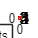


legend([ dot,p(1),p(2),p(3),p(4),p(5)]);
xlabel('x(m)');
ylabel('y(m)');
zlabel('z(m)')


grid on

view([180 90.00])

### Save New Data

folder='dataset'; 
if exist(folder)==0 
    mkdir(folder); 
end
datasetname='cooldata';
savename=[folder,'/',datasetname,'.mat'];
save(savename);

% 
f=gcf;
% name = [datasetname,'.pdf'];
% savepath1 = [folder,'/',name];
% exportgraphics(f,savepath1)
